clc;clear;

% 初始化参数
algorithms = {'EEI', 'ParEGO', 'DISK', 'PIMD'};  % 算法名称列表
num_experiments = 5;     % 5次实验
eval_points = 200;       % 总评估点数
output_length = eval_points - 19;  % 输出数据长度 (200-20+1=181)

% 用结构体存储所有数据（比eval更安全、更高效）
datasets = struct();

% 主循环：遍历所有算法
for alg_idx = 1:length(algorithms)
    alg_name = algorithms{alg_idx};
    
    % 初始化当前算法的存储矩阵
    datasets.(alg_name) = zeros(num_experiments, output_length);
    
    % 遍历5次实验
    for exp_num = 1:num_experiments
        % 加载数据文件
        if alg_name == "EEI"
            filename = sprintf('result_time/%s_DATA_100for70_200_%d.mat', alg_name, exp_num);
        else
            filename = sprintf('%s_DATA_100for70_200_%d.mat', alg_name, exp_num);
        end
        load(filename);
        
        % 统一数据变量名
        if strcmp(alg_name, 'EEI') || strcmp(alg_name, 'ParEGO')
            Obj = eval([alg_name '_DATA.y']);  % 这里可以进一步优化，但需要知道数据结构
        else
            Obj = DB.y;  % DISK和DEGA的数据存储在DB中
        end
        
        % 非支配排序
        [a, ~] = NDSort(Obj, 1);
        
        % 计算前20个评估点的Pareto点数量
        count = sum(a(1:20) == 1);
        datasets.(alg_name)(exp_num, 1) = count;
        
        % 累积计算21-200评估点的Pareto点数量
        for k = 21:eval_points
            col_idx = k - 19;  % 因为k=21对应第2列
            if a(k) == 1
                datasets.(alg_name)(exp_num, col_idx) = datasets.(alg_name)(exp_num, col_idx-1) + 1;
            else
                datasets.(alg_name)(exp_num, col_idx) = datasets.(alg_name)(exp_num, col_idx-1);
            end
        end
    end
end

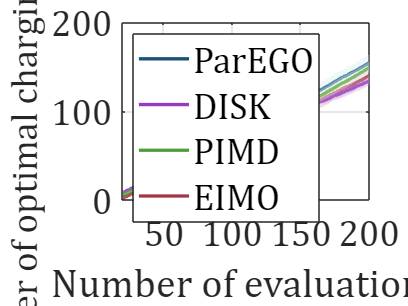

% 计算各算法的均值和标准差
EEI_mean = mean(datasets.EEI);
PAR_mean = mean(datasets.ParEGO);
DISK_mean = mean(datasets.DISK);
PIMD_mean = mean(datasets.PIMD);

EEI_std = std(datasets.EEI);
PAR_std = std(datasets.ParEGO);
DISK_std = std(datasets.DISK);
PIMD_std = std(datasets.PIMD);

% 使用您指定的颜色方案
c = ['#A43546';'#1A5276';'#963CC2';'#4E9E35']; % 主色（红/蓝/紫/绿）
cc = [[220,144,156]/255;...    % EEI误差带色（主色1浅色）
      [199,229,237]/255;...    % ParEGO误差带色（主色2浅色）
      [200,157,222]/255;...    % DISK误差带色（主色3浅色）
      [233,255,233]/255];      % DEGA误差带色（主色4浅色）
facealpha = 0.3;               % 误差带透明度
lw = 2;                        % 线宽

% 创建图形
figure(1);
clf;
set(gcf, 'Position', [100 100 800 600], 'Color', 'w');
it = 20:1:200;

% ===== 绘制EEI (红色) =====
p1 = plot(it, EEI_mean, '-', 'LineWidth', lw, 'Color', '#A43546');
hold on;
fill([it, fliplr(it)], [EEI_mean+EEI_std, fliplr(EEI_mean-EEI_std)],...
     cc(1,:), 'FaceAlpha', facealpha, 'EdgeColor', 'none');

% ===== 绘制ParEGO (蓝色) ===== 
p2 = plot(it, PAR_mean, '-', 'LineWidth', lw, 'Color', '#1A5276');
fill([it, fliplr(it)], [PAR_mean+PAR_std, fliplr(PAR_mean-PAR_std)],...
     cc(2,:), 'FaceAlpha', facealpha, 'EdgeColor', 'none');

% ===== 绘制DISK (紫色) =====
p3 = plot(it, DISK_mean, '-', 'LineWidth', lw, 'Color', '#963CC2');
fill([it, fliplr(it)], [DISK_mean+DISK_std, fliplr(DISK_mean-DISK_std)],...
     cc(3,:), 'FaceAlpha', facealpha, 'EdgeColor', 'none');

% ===== 绘制DEGA (绿色) =====
p4 = plot(it, PIMD_mean, '-', 'LineWidth', lw, 'Color', '#4E9E35');
fill([it, fliplr(it)], [PIMD_mean+PIMD_std, fliplr(PIMD_mean-PIMD_std)],...
     cc(4,:), 'FaceAlpha', facealpha, 'EdgeColor', 'none');

% ===== 图形修饰 =====
grid on;
xlim([20, 200]);
legend([p2, p3, p4, p1], {'ParEGO','DISK','PIMD','EIMO'},...
       'Location', 'northwest', 'FontSize', 22);
xlabel('Number of evaluations', 'FontSize', 22);
ylabel('Number of optimal charging protocols', 'FontSize', 22);
set(gca, 'FontName', 'Cambria', 'FontSize', 22, 'Box', 'on');

% 添加您的特殊标注（如需）
ylab = ylabel('Number of optimal charging protocols');
set(ylab, 'FontSize', 22);


% 保存图形（可选）
% exportgraphics(gcf, 'algorithm_comparison.png', 'Resolution', 300);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clc;clear;

% 初始化参数
algorithms = {'EEI', 'ParEGO', 'DISK', 'PIMD'};  % 算法名称列表
num_experiments = 5;     % 5次实验
eval_points = 200;       % 总评估点数
output_length = eval_points - 19;  % 输出数据长度 (200-20+1=181)

% 用结构体存储所有数据（比eval更安全、更高效）
datasets = struct();

% 主循环：遍历所有算法
for alg_idx = 1:length(algorithms)
    alg_name = algorithms{alg_idx};
    
    % 初始化当前算法的存储矩阵
    datasets.(alg_name) = zeros(num_experiments, output_length);
    
    % 遍历5次实验
    for exp_num = 1:num_experiments
        % 加载数据文件
        filename = sprintf('%s_DATA_90for70_200_%d.mat', alg_name, exp_num);
        load(filename);
        
        % 统一数据变量名
        if strcmp(alg_name, 'EEI') || strcmp(alg_name, 'ParEGO')
            Obj = eval([alg_name '_DATA.y']);  % 这里可以进一步优化，但需要知道数据结构
        else
            Obj = DB.y;  % DISK和DEGA的数据存储在DB中
        end
        
        % 非支配排序
        [a, ~] = NDSort(Obj, 1);
        
        % 计算前20个评估点的Pareto点数量
        count = sum(a(1:20) == 1);
        datasets.(alg_name)(exp_num, 1) = count;
        
        % 累积计算21-200评估点的Pareto点数量
        for k = 21:eval_points
            col_idx = k - 19;  % 因为k=21对应第2列
            if a(k) == 1
                datasets.(alg_name)(exp_num, col_idx) = datasets.(alg_name)(exp_num, col_idx-1) + 1;
            else
                datasets.(alg_name)(exp_num, col_idx) = datasets.(alg_name)(exp_num, col_idx-1);
            end
        end
    end
end

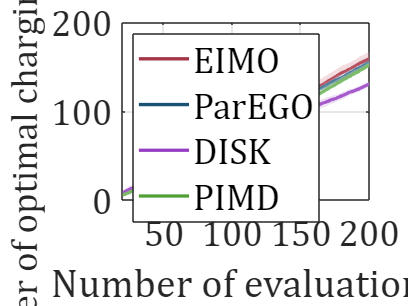

% 计算各算法的均值和标准差
EEI_mean = mean(datasets.EEI);
PAR_mean = mean(datasets.ParEGO);
DISK_mean = mean(datasets.DISK);
PIMD_mean = mean(datasets.PIMD);

EEI_std = std(datasets.EEI);
PAR_std = std(datasets.ParEGO);
DISK_std = std(datasets.DISK);
PIMD_std = std(datasets.PIMD);

% 使用您指定的颜色方案
c = ['#A43546';'#1A5276';'#963CC2';'#4E9E35']; % 主色（红/蓝/紫/绿）
cc = [[220,144,156]/255;...    % EEI误差带色（主色1浅色）
      [199,229,237]/255;...    % ParEGO误差带色（主色2浅色）
      [200,157,222]/255;...    % DISK误差带色（主色3浅色）
      [233,255,233]/255];      % DEGA误差带色（主色4浅色）
facealpha = 0.3;               % 误差带透明度
lw = 2;                        % 线宽

% 创建图形
figure(1);
clf;
set(gcf, 'Position', [100 100 800 600], 'Color', 'w');
it = 20:1:200;

% ===== 绘制EEI (红色) =====
p1 = plot(it, EEI_mean, '-', 'LineWidth', lw, 'Color', '#A43546');
hold on;
fill([it, fliplr(it)], [EEI_mean+EEI_std, fliplr(EEI_mean-EEI_std)],...
     cc(1,:), 'FaceAlpha', facealpha, 'EdgeColor', 'none');

% ===== 绘制ParEGO (蓝色) ===== 
p2 = plot(it, PAR_mean, '-', 'LineWidth', lw, 'Color', '#1A5276');
fill([it, fliplr(it)], [PAR_mean+PAR_std, fliplr(PAR_mean-PAR_std)],...
     cc(2,:), 'FaceAlpha', facealpha, 'EdgeColor', 'none');

% ===== 绘制DISK (紫色) =====
p3 = plot(it, DISK_mean, '-', 'LineWidth', lw, 'Color', '#963CC2');
fill([it, fliplr(it)], [DISK_mean+DISK_std, fliplr(DISK_mean-DISK_std)],...
     cc(3,:), 'FaceAlpha', facealpha, 'EdgeColor', 'none');

% ===== 绘制DEGA (绿色) =====
p4 = plot(it, PIMD_mean, '-', 'LineWidth', lw, 'Color', '#4E9E35');
fill([it, fliplr(it)], [PIMD_mean+PIMD_std, fliplr(PIMD_mean-PIMD_std)],...
     cc(4,:), 'FaceAlpha', facealpha, 'EdgeColor', 'none');

% ===== 图形修饰 =====
grid on;
xlim([20, 200]);
legend([p1, p2, p3, p4], {'EIMO','ParEGO','DISK','PIMD'},...
       'Location', 'northwest', 'FontSize', 22);
xlabel('Number of evaluations', 'FontSize', 22);
ylabel('Number of optimal charging protocols', 'FontSize', 22);
set(gca, 'FontName', 'Cambria', 'FontSize', 22, 'Box', 'on');

% 添加您的特殊标注（如需）
ylab = ylabel('Number of optimal charging protocols');
set(ylab, 'FontSize', 22);


% 保存图形（可选）
% exportgraphics(gcf, 'algorithm_comparison.png', 'Resolution', 300);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clc;clear;

% 初始化参数
algorithms = {'EEI', 'ParEGO', 'DISK', 'PIMD'};  % 算法名称列表
num_experiments = 5;     % 5次实验
eval_points = 200;       % 总评估点数
output_length = eval_points - 19;  % 输出数据长度 (200-20+1=181)

% 用结构体存储所有数据（比eval更安全、更高效）
datasets = struct();

% 主循环：遍历所有算法
for alg_idx = 1:length(algorithms)
    alg_name = algorithms{alg_idx};
    
    % 初始化当前算法的存储矩阵
    datasets.(alg_name) = zeros(num_experiments, output_length);
    
    % 遍历5次实验
    for exp_num = 1:num_experiments
        % 加载数据文件
        filename = sprintf('%s_DATA_80for70_200_%d.mat', alg_name, exp_num);
        load(filename);
        
        % 统一数据变量名
        if strcmp(alg_name, 'EEI') || strcmp(alg_name, 'ParEGO')
            Obj = eval([alg_name '_DATA.y']);  % 这里可以进一步优化，但需要知道数据结构
        else
            Obj = DB.y;  % DISK和DEGA的数据存储在DB中
        end
        
        % 非支配排序
        [a, ~] = NDSort(Obj, 1);
        
        % 计算前20个评估点的Pareto点数量
        count = sum(a(1:20) == 1);
        datasets.(alg_name)(exp_num, 1) = count;
        
        % 累积计算21-200评估点的Pareto点数量
        for k = 21:eval_points
            col_idx = k - 19;  % 因为k=21对应第2列
            if a(k) == 1
                datasets.(alg_name)(exp_num, col_idx) = datasets.(alg_name)(exp_num, col_idx-1) + 1;
            else
                datasets.(alg_name)(exp_num, col_idx) = datasets.(alg_name)(exp_num, col_idx-1);
            end
        end
    end
end

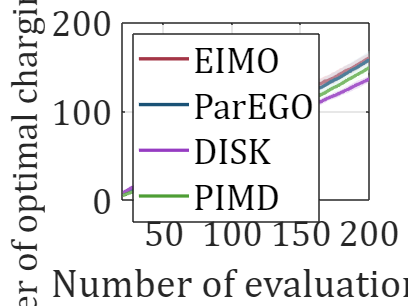

% 计算各算法的均值和标准差
EEI_mean = mean(datasets.EEI);
PAR_mean = mean(datasets.ParEGO);
DISK_mean = mean(datasets.DISK);
PIMD_mean = mean(datasets.PIMD);

EEI_std = std(datasets.EEI);
PAR_std = std(datasets.ParEGO);
DISK_std = std(datasets.DISK);
PIMD_std = std(datasets.PIMD);

% 使用您指定的颜色方案
c = ['#A43546';'#1A5276';'#963CC2';'#4E9E35']; % 主色（红/蓝/紫/绿）
cc = [[220,144,156]/255;...    % EEI误差带色（主色1浅色）
      [199,229,237]/255;...    % ParEGO误差带色（主色2浅色）
      [200,157,222]/255;...    % DISK误差带色（主色3浅色）
      [233,255,233]/255];      % DEGA误差带色（主色4浅色）
facealpha = 0.3;               % 误差带透明度
lw = 2;                        % 线宽

% 创建图形
figure(1);
clf;
set(gcf, 'Position', [100 100 800 600], 'Color', 'w');
it = 20:1:200;

% ===== 绘制EEI (红色) =====
p1 = plot(it, EEI_mean, '-', 'LineWidth', lw, 'Color', '#A43546');
hold on;
fill([it, fliplr(it)], [EEI_mean+EEI_std, fliplr(EEI_mean-EEI_std)],...
     cc(1,:), 'FaceAlpha', facealpha, 'EdgeColor', 'none');

% ===== 绘制ParEGO (蓝色) ===== 
p2 = plot(it, PAR_mean, '-', 'LineWidth', lw, 'Color', '#1A5276');
fill([it, fliplr(it)], [PAR_mean+PAR_std, fliplr(PAR_mean-PAR_std)],...
     cc(2,:), 'FaceAlpha', facealpha, 'EdgeColor', 'none');

% ===== 绘制DISK (紫色) =====
p3 = plot(it, DISK_mean, '-', 'LineWidth', lw, 'Color', '#963CC2');
fill([it, fliplr(it)], [DISK_mean+DISK_std, fliplr(DISK_mean-DISK_std)],...
     cc(3,:), 'FaceAlpha', facealpha, 'EdgeColor', 'none');

% ===== 绘制DEGA (绿色) =====
p4 = plot(it, PIMD_mean, '-', 'LineWidth', lw, 'Color', '#4E9E35');
fill([it, fliplr(it)], [PIMD_mean+PIMD_std, fliplr(PIMD_mean-PIMD_std)],...
     cc(4,:), 'FaceAlpha', facealpha, 'EdgeColor', 'none');

% ===== 图形修饰 =====
grid on;
xlim([20, 200]);
legend([p1, p2, p3, p4], {'EIMO','ParEGO','DISK','PIMD'},...
       'Location', 'northwest', 'FontSize', 22);
xlabel('Number of evaluations', 'FontSize', 22);
ylabel('Number of optimal charging protocols', 'FontSize', 22);
set(gca, 'FontName', 'Cambria', 'FontSize', 22, 'Box', 'on');

% 添加您的特殊标注（如需）
ylab = ylabel('Number of optimal charging protocols');
set(ylab, 'FontSize', 22);


% 保存图形（可选）
% exportgraphics(gcf, 'algorithm_comparison.png', 'Resolution', 300);

clc;clear;
dataset_EEI = zeros(5,181);
dataset_PAR = zeros(5,181);

%%%%%%%%%%%%%%%%%%%%%%%%%
load("EEI_DATA_90for70_200_1.mat");
Obj = EEI_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_EEI(1,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_EEI(1,k-19) = dataset_EEI(1,k-20)+1;
    else
        dataset_EEI(1,k-19) = dataset_EEI(1,k-20);
    end
end

load("ParEGO_DATA_90for70_200_1.mat");
Obj = ParEGO_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_PAR(1,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_PAR(1,k-19) = dataset_PAR(1,k-20)+1;
    else
        dataset_PAR(1,k-19) = dataset_PAR(1,k-20);
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%
load("EEI_DATA_90for70_200_2.mat");
Obj = EEI_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_EEI(2,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_EEI(2,k-19) = dataset_EEI(2,k-20)+1;
    else
        dataset_EEI(2,k-19) = dataset_EEI(2,k-20);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%
load("EEI_DATA_90for70_200_3.mat");
Obj = EEI_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_EEI(3,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_EEI(3,k-19) = dataset_EEI(3,k-20)+1;
    else
        dataset_EEI(3,k-19) = dataset_EEI(3,k-20);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%
load("EEI_DATA_90for70_200_4.mat");
Obj = EEI_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_EEI(4,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_EEI(4,k-19) = dataset_EEI(4,k-20)+1;
    else
        dataset_EEI(4,k-19) = dataset_EEI(4,k-20);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%
load("EEI_DATA_90for70_200_5.mat");
Obj = EEI_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_EEI(5,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_EEI(5,k-19) = dataset_EEI(5,k-20)+1;
    else
        dataset_EEI(5,k-19) = dataset_EEI(5,k-20);
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%
load("ParEGO_DATA_90for70_200_1.mat");
Obj = ParEGO_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_PAR(1,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_PAR(1,k-19) = dataset_PAR(1,k-20)+1;
    else
        dataset_PAR(1,k-19) = dataset_PAR(1,k-20);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%
load("ParEGO_DATA_90for70_200_2.mat");
Obj = ParEGO_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_PAR(2,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_PAR(2,k-19) = dataset_PAR(2,k-20)+1;
    else
        dataset_PAR(2,k-19) = dataset_PAR(2,k-20);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%
load("ParEGO_DATA_90for70_200_3.mat");
Obj = ParEGO_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_PAR(3,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_PAR(3,k-19) = dataset_PAR(3,k-20)+1;
    else
        dataset_PAR(3,k-19) = dataset_PAR(3,k-20);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%
load("ParEGO_DATA_90for70_200_4.mat");
Obj = ParEGO_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_PAR(4,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_PAR(4,k-19) = dataset_PAR(4,k-20)+1;
    else
        dataset_PAR(4,k-19) = dataset_PAR(4,k-20);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%
load("ParEGO_DATA_90for70_200_5.mat");
Obj = ParEGO_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_PAR(5,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_PAR(5,k-19) = dataset_PAR(5,k-20)+1;
    else
        dataset_PAR(5,k-19) = dataset_PAR(5,k-20);
    end
end

EEI_mean = mean(dataset_EEI);
PAR_mean = mean(dataset_PAR);
EEI_std = std(dataset_EEI);
PAR_std = std(dataset_PAR);

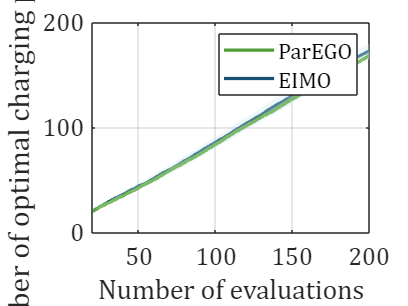

c = ['#A43546';'#1A5276';'#963CC2';'#4E9E35';'#AAAC4D';'#26F1F1'];
cc = [[220,144,156]/255;...
    [199,229,237]/255;[200,157,222]/255;...
    [233,255,233]/255;[252,255,228]/255;[216,255,255]/255];
lw = 2;
facealpha = 0.3;
% 绘制图像
close(figure(1));
figure(1);
it = 20:1:200;
p1 = plot(it,EEI_mean,...
    '-','LineWidth',lw,...
    'color',c(2,:),'MarkerSize',1);
hold on;
grid on;
y1 = EEI_mean+EEI_std;
y2 = EEI_mean-EEI_std;
h = fill([it,fliplr(it)],[y1,fliplr(y2)],cc(2,:));
set(h,'edgealpha',0,'facealpha',facealpha);

p2 = plot(it,PAR_mean,...
    '-','LineWidth',lw,...
    'color',c(4,:),'MarkerSize',1);
y1 = PAR_mean+PAR_std;
y2 = PAR_mean-PAR_std;
h = fill([it,fliplr(it)],[y1,fliplr(y2)],cc(4,:));
set(h,'edgealpha',0,'facealpha',facealpha) 

xlim([20,200]);
legend([p2,p1],'ParEGO','EIMO');
xlabel('Number of evaluations');
ylab = ylabel('Number of optimal charging protocols');
set(gca,'fontname','Cambria','fontsize',15);
set(ylab,'fontsize',18);

% title("Using experiences from SOH=0.9 for SOH=0.8");

%%

clc;clear;
dataset_EEI = zeros(5,181);
dataset_PAR = zeros(5,181);

%%%%%%%%%%%%%%%%%%%%%%%%%
load("EEI_DATA_80for70_200_1.mat");
Obj = EEI_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_EEI(1,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_EEI(1,k-19) = dataset_EEI(1,k-20)+1;
    else
        dataset_EEI(1,k-19) = dataset_EEI(1,k-20);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%
load("EEI_DATA_80for70_200_2.mat");
Obj = EEI_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_EEI(2,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_EEI(2,k-19) = dataset_EEI(2,k-20)+1;
    else
        dataset_EEI(2,k-19) = dataset_EEI(2,k-20);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%
load("EEI_DATA_80for70_200_3.mat");
Obj = EEI_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_EEI(3,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_EEI(3,k-19) = dataset_EEI(3,k-20)+1;
    else
        dataset_EEI(3,k-19) = dataset_EEI(3,k-20);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%
load("EEI_DATA_80for70_200_4.mat");
Obj = EEI_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_EEI(4,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_EEI(4,k-19) = dataset_EEI(4,k-20)+1;
    else
        dataset_EEI(4,k-19) = dataset_EEI(4,k-20);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%
load("EEI_DATA_80for70_200_5.mat");
Obj = EEI_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_EEI(5,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_EEI(5,k-19) = dataset_EEI(5,k-20)+1;
    else
        dataset_EEI(5,k-19) = dataset_EEI(5,k-20);
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%
load("ParEGO_DATA_80for70_200_1.mat");
Obj = ParEGO_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_PAR(1,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_PAR(1,k-19) = dataset_PAR(1,k-20)+1;
    else
        dataset_PAR(1,k-19) = dataset_PAR(1,k-20);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%
load("ParEGO_DATA_80for70_200_2.mat");
Obj = ParEGO_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_PAR(2,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_PAR(2,k-19) = dataset_PAR(2,k-20)+1;
    else
        dataset_PAR(2,k-19) = dataset_PAR(2,k-20);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%
load("ParEGO_DATA_80for70_200_3.mat");
Obj = ParEGO_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_PAR(3,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_PAR(3,k-19) = dataset_PAR(3,k-20)+1;
    else
        dataset_PAR(3,k-19) = dataset_PAR(3,k-20);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%
load("ParEGO_DATA_80for70_200_4.mat");
Obj = ParEGO_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_PAR(4,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_PAR(4,k-19) = dataset_PAR(4,k-20)+1;
    else
        dataset_PAR(4,k-19) = dataset_PAR(4,k-20);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%
load("ParEGO_DATA_80for70_200_5.mat");
Obj = ParEGO_DATA.y;
[a,~] = NDSort(Obj,1);
count = 0;
for k = 1:20
    count = count + 1;
end
dataset_PAR(5,1) = count;
for k = 21:200
    if a(k) == 1
        dataset_PAR(5,k-19) = dataset_PAR(5,k-20)+1;
    else
        dataset_PAR(5,k-19) = dataset_PAR(5,k-20);
    end
end

EEI_mean = mean(dataset_EEI);
PAR_mean = mean(dataset_PAR);
EEI_std = std(dataset_EEI);
PAR_std = std(dataset_PAR); 

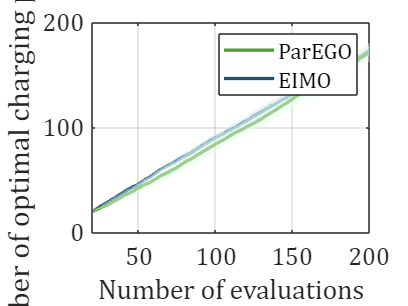

c = ['#A43546';'#1A5276';'#963CC2';'#4E9E35';'#AAAC4D';'#26F1F1'];
cc = [[220,144,156]/255;...
    [199,229,237]/255;[200,157,222]/255;...
    [233,255,233]/255;[252,255,228]/255;[216,255,255]/255];
lw = 2;
facealpha = 0.5;
% 绘制图像
close(figure(1));
figure(1);
it = 20:1:200;
p1 = plot(it,EEI_mean,...
    '-','LineWidth',lw,...
    'color',c(2,:),'MarkerSize',1);
hold on;
grid on;
y1 = EEI_mean+EEI_std;
y2 = EEI_mean-EEI_std;
h = fill([it,fliplr(it)],[y1,fliplr(y2)],cc(2,:));
set(h,'edgealpha',0,'facealpha',facealpha);

p2 = plot(it,PAR_mean,...
    '-','LineWidth',lw,...
    'color',c(4,:),'MarkerSize',1);
y1 = PAR_mean+PAR_std;
y2 = PAR_mean-PAR_std;
h = fill([it,fliplr(it)],[y1,fliplr(y2)],cc(4,:));
set(h,'edgealpha',0,'facealpha',facealpha);

xlim([20,200]);
legend([p2,p1],'ParEGO','EIMO');
xlabel('Number of evaluations');
ylab = ylabel('Number of optimal charging protocols');
set(gca,'fontname','Cambria','fontsize',15);
set(ylab,'fontsize',18);

% title("Using experiences from SOH=0.8");